# `Background Separation `

#### `From the Robust PCA Applications`

clc
close all
clear all

`The processing of video falls within the domain of image processing, where the available data is in the form of video format. Each video consists of a sequence of images, and processing it poses challenges due to the volume of data and the spatial dimensions of the data, leading to resource limitations in computer processing.`

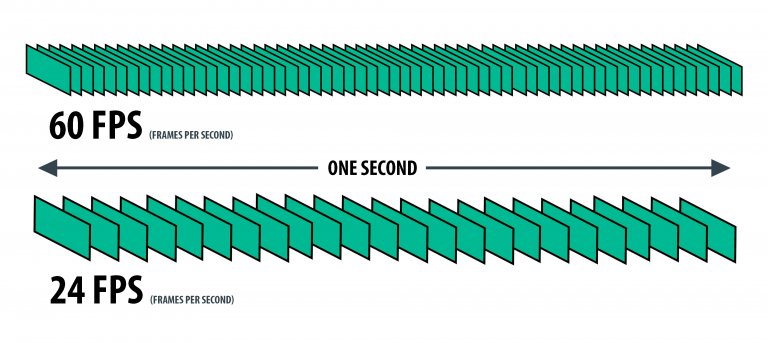

`Therefore, efforts are always made to reduce data complexity through various methods, including deleting less important information or changing the display space.`

`In this section, we intend to ``remove the background of a color video ``using vector-based methods.`

### `I. ``Introduction:`

`Tensors are mathematical structures that represent multilinear relationships among a set of numbers, vectors, and other tensors. Tensors can have any number of dimensions and are used to represent a wide range of quantities and physical phenomena. Some of these applications include the representation of the curvature of space-time in general relativity, the depiction of stress and strain in the mechanics of materials, and the description of quantum states of particles in quantum mechanics.`

`Tensors, possessing algebraic matrix-like properties such as multiplication, addition, and transposition, allow many algebraic concepts, including eigenvalues, determinants, and decompositions like singular value decomposition, to be generalized for them.`

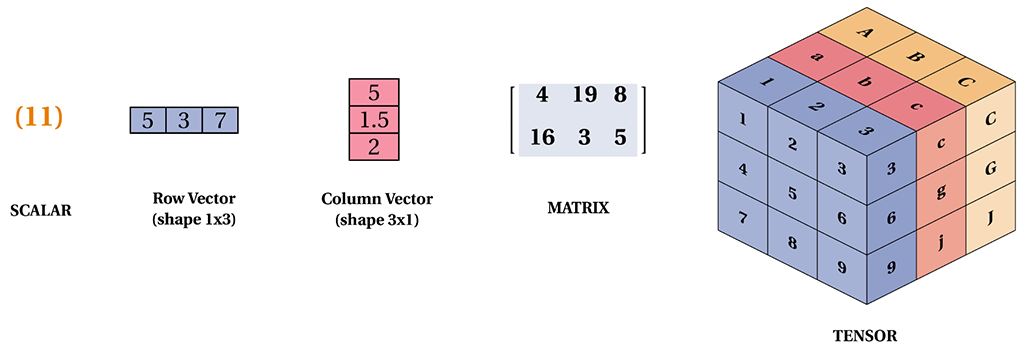

`Tensors can be defined as linear mappings between different vector spaces, which is a fundamental concept in linear algebra. This topic enables various operations such as rotation, scaling, and others to be performed using tensors, playing a crucial role in many applications.`

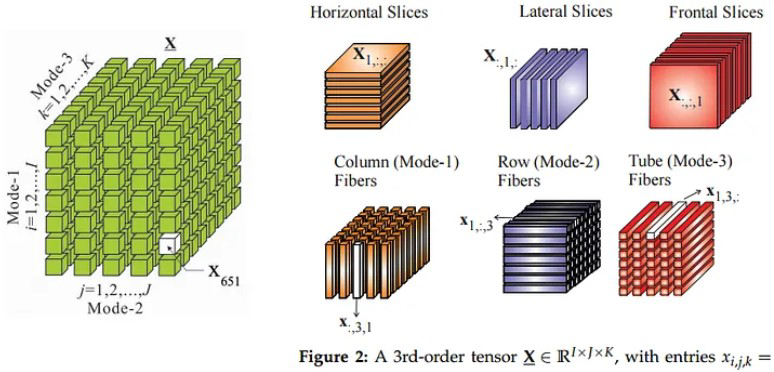

`The number of dimensions of a tensor is commonly referred to as its rank or order. Accessing a specific element of a tensor, known as tensor slicing, involves referring to the first dimension of the tensor as the sample axis.`

### `II. Principal Component Analysis (PCA): `

`PCA (Principal Component Analysis) is one of the methods for dimensionality reduction while preserving the maximum possible information. In this method, the space is projected onto axes where the data images have the highest variance.`

`It is established that the best axes for this projection are the eigenvectors of the covariance matrix with the corresponding eigenvalues being the highest. For a better understanding of this concept, it is recommended to study this `[`interactive booklet`](https://setosa.io/ev/principal-component-analysis/)`!`

`This method has numerous applications in medical, financial, textual, and other types of data.`

### `III. Eigenvalues & Eigenvectors: `

`Roughly, for almost all vectors, the direction changes when they are multiplied by the desired matrix A, except for specific vectors called eigenvectors. The size change of these vectors corresponds to the eigenvalue magnitude. For a better understanding of this concept, it is recommended to read this `[`interactive booklet`](https://setosa.io/ev/eigenvectors-and-eigenvalues/)`.`

### `IV. Comprehensive Questions:`

`1. Write about the application of image processing in it and conduct research on Tensor data structure with a relationship in it.`

`Answer:` `The application of image processing encompasses a wide range of fields, and its significance extends to various domains such as computer vision, medical imaging, satellite imagery analysis, and more. Image processing involves manipulating and analyzing images to extract meaningful information or enhance visual quality.`

`In the context of research, exploring the integration of Tensor data structures adds a layer of complexity and depth to image processing studies. Tensors are multi-dimensional arrays that can represent data in the form of higher-order structures. In the realm of image processing, Tensors can be particularly valuable due to their ability to capture and represent complex relationships within image data.`

`Conducting research on Tensor data structures within the framework of image processing involves investigating how Tensors can be effectively utilized for tasks such as image recognition, object detection, and image synthesis. Tensors enable researchers to model intricate relationships and dependencies within image datasets, allowing for more advanced and accurate analysis.`

`Moreover, the relationship between Tensor data structures and image processing lies in the capacity of Tensors to handle multi-dimensional data. Images, being inherently multi-dimensional (with height, width, and channels), can be naturally represented using Tensor structures. Understanding and exploiting this relationship can lead to innovative approaches in image processing algorithms, contributing to advancements in fields like machine learning and artificial intelligence.`

`In summary, the application of image processing in various domains, coupled with the exploration of Tensor data structures, opens up new avenues for research and innovation. The integration of Tensors enhances the capability of image processing techniques, paving the way for more sophisticated and effective solutions in the analysis and manipulation of visual data.`

`2. Explain Robust PCA and discuss its differences with PCA. Also, provide pseudo-code for this algorithm.`

`Answer:`` Robust Principal Component Analysis (Robust PCA) is an extension of traditional Principal Component Analysis (PCA) that is designed to be more resilient to outliers and corrupted data. PCA is a dimensionality reduction technique that identifies the principal components of a dataset, allowing for a lower-dimensional representation of the data while retaining most of its variability. However, PCA is sensitive to outliers and can be influenced by extreme values in the dataset.`

`Robust PCA addresses this issue by introducing robustness to outliers. It achieves this by decomposing the input data matrix into low-rank and sparse components. The low-rank component captures the main structure of the data, while the sparse component represents the outliers or errors. The optimization problem involved in Robust PCA minimizes the rank of the low-rank component and the sparsity of the sparse component simultaneously.`

`Differences between`` Robust PCA and PCA:`

- `Outlier Sensitivity:`

`PCA:`` PCA is sensitive to outliers as it aims to minimize the overall variance.`

`Robust PCA:`` Robust PCA is designed to be more resilient to outliers, effectively separating the low-rank structure from the sparse outliers.`

- `Optimization Problem:`

`PCA:`` PCA involves solving an optimization problem based on maximizing variance and minimizing reconstruction error.`

`Robust PCA:`` Robust PCA solves an optimization problem that includes minimizing the rank of the low-rank component and the sparsity of the sparse component.`

- `Application:`

`PCA:`` PCA is widely used for dimensionality reduction, feature extraction, and data compression.`

`Robust PCA:`` Robust PCA is particularly useful when dealing with datasets that may contain outliers or corrupted data, such as in computer vision, image processing, and video analysis.`

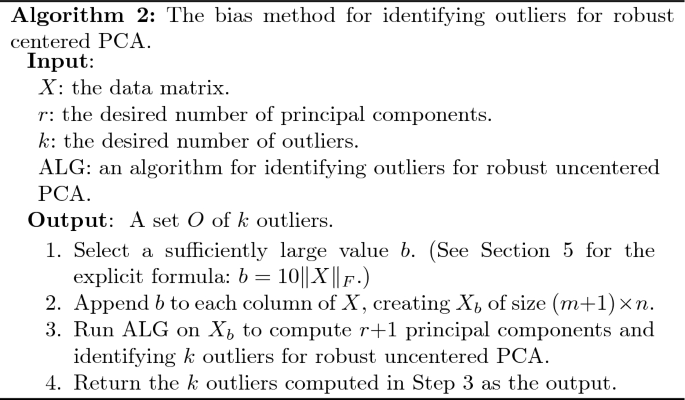

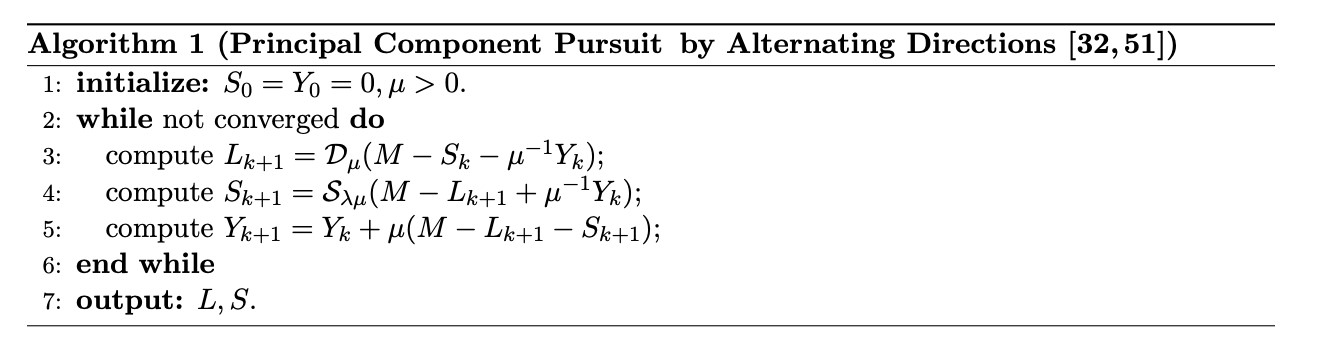

`This pseudo-code uses the PCP approach to solve the Robust PCA optimization problem iteratively. The SVT operator is employed for the singular value thresholding step. Adjust the lambda_val parameter based on the desired level of sparsity in the sparse component.`

`3. Search about Higher-order SVD, Truncated SVD, Randomized SVD, and highlight their differences compared to SVD.`

`Answer: ``Higher-order SVD, Truncated SVD, and Randomized SVD are variants of Singular Value Decomposition (SVD), a mathematical technique used in linear algebra and data analysis. Here are brief explanations of each, along with their differences compared to traditional SVD:`

`3-1. Higher-order SVD``:`

- `Definition:`` Higher-order SVD generalizes the concept of SVD to tensors of order greater than two. While traditional SVD deals with matrices (order-two tensors), higher-order SVD extends the decomposition to higher-dimensional data structures like tensors.`

- `Differences with SVD:`` The primary distinction lies in the input data type. Higher-order SVD is designed for tensors, capturing multi-dimensional relationships beyond the scope of matrices.`

`3-2. Truncated SVD:`

- `Definition:`` Truncated SVD is a method that approximates the original matrix by retaining only a specified number of the most significant singular values and their corresponding vectors.`

- `Differences with SVD:`` Unlike traditional SVD, which decomposes a matrix into its exact singular components, truncated SVD provides an approximation by retaining only the most important information. This can be useful for reducing the dimensionality of the data.`

`3-3. Randomized SVD:`

- `Definition:`` Randomized SVD is an algorithmic approach to compute an approximate SVD by using randomization techniques. It provides an efficient way to approximate the dominant singular values and vectors of a matrix.`

- `Differences with SVD:`` Randomized SVD introduces a randomized element to the computation, making it more scalable and suitable for large datasets. It sacrifices some precision for computational efficiency, which can be advantageous in certain applications.`

`In summary, while SVD is the foundational concept, these variants offer specialized approaches to address specific challenges such as higher-dimensional data (Higher-order SVD), dimensionality reduction (Truncated SVD), and computational efficiency for large datasets (Randomized SVD). The choice of which method to use depends on the nature of the data and the specific goals of the analysis.`

`4. Write the Nuclear Norm relation.`

`Answer: ``Nuclear, or trace, or Ky Fan, norm of a matrix is defined as the sum of the singular values of the matrix.`

`It is claimed that`


$$\parallel X\parallel_{\sigma } \;=\min_{{\textrm{UV}}^T =X} \parallel U\parallel \parallel V\parallel =\min_{{\textrm{UV}}^T =X} \frac{1}{2}\left(\parallel U\parallel^2 +\parallel V\parallel^2 \right)$$


`where `$\parallel \ldotp \parallel_{\sigma }$` is the nuclear norm of `$X$` and `$\parallel \cdot \parallel$` is the Frobenius norm.`


$$\parallel X\parallel_{\sigma } \;=\textrm{tr}\left(S\right)=\textrm{tr}\left(A^T {\textrm{UV}}^T B\right)\le \;\parallel \textrm{ATU}\parallel \parallel \textrm{VTB}\parallel \;=\;\parallel U\parallel \parallel V\parallel \;\le \;\frac{1}{2}\left(\parallel U\parallel^2 +\parallel V\parallel^2 \right)$$


### `V. Implementation:`

`A video named "``Indiantraffic.avi"`` has been attached to the project file with a frame rate of ``20 fps``. While reading this video in the Tensor structure, display an arbitrary frame and mention the image resolution. The existing Tensor is multidimensional, and each dimension represents what characteristic of the video?`

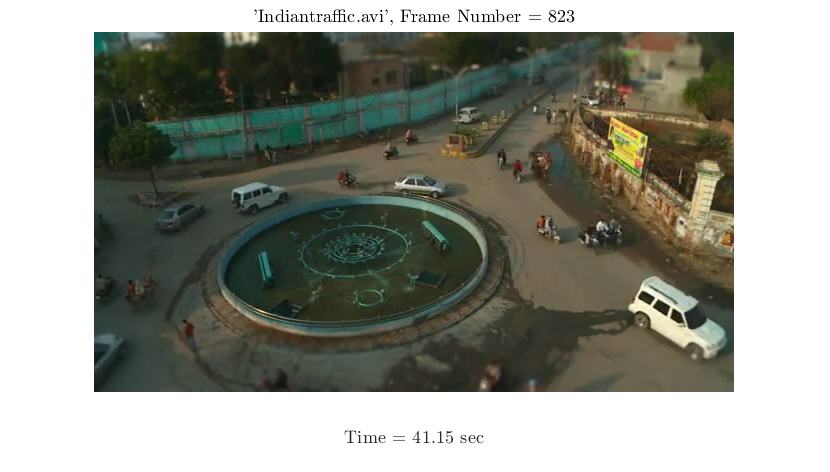

indiantraffic = VideoReader("Indiantraffic.avi");
height = indiantraffic.Height;
width = indiantraffic.Width;
duration_in_sec = indiantraffic.Duration;
frame_rate = indiantraffic.FrameRate;
frame_num = round(frame_rate * duration_in_sec);
rgb_film = indiantraffic.read;
rgb_film_size = size(rgb_film);
frame_ind = randi(frame_num);
frame_data = rgb_film(:,:,:,frame_ind);
figure
imshow(frame_data);
title("'Indiantraffic.avi', Frame Number = " + num2str(frame_ind), Interpreter = "latex");
xlabel("Time = " + num2str(frame_ind/rgb_film_size(4)*duration_in_sec) + " sec", Interpreter = "latex");

fprintf('Resolution: %d * %d\n', height, width)

Resolution: 360 * 640


`To reduce computational complexity, convert the video to black and white, and then add ``Salt-and-pepper noise`` to it.`

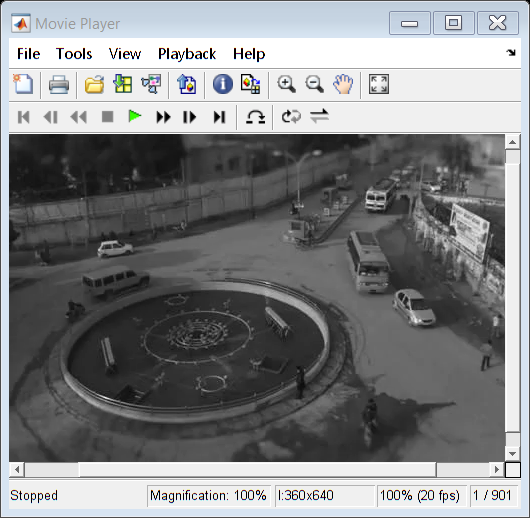

gray_film = zeros(height, width, frame_num);
noisy_gray_film = zeros(height, width, frame_num);
for i = 1:frame_num
    gray_film(:,:,i) = double(rgb2gray(rgb_film(:,:,:,i))) / 2^8;
    noisy_gray_film(:,:,i) = imnoise(gray_film(:,:,i), 'salt & pepper');
end
implay(gray_film);

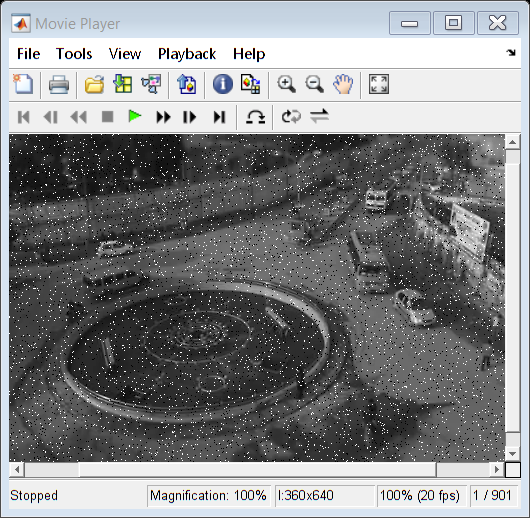

implay(noisy_gray_film);

`Using Robust PCA, decompose the existing Tensor into two tensors: Low Rank and Sparse. Finally, report the Reconstruction Error and explain this error.`

`Display an arbitrary frame from the two tensors, Low Rank and Sparse, and explain them. Can the background be removed with just one frame (image) in this method? Discuss.`

- `Recontruction Error: ``The reconstruction error in PCA (Principal Component Analysis) represents the difference between the original data points and their projections onto the lower-dimensional space defined by the principal components. It quantifies how well the lower-dimensional representation preserves the information from the original data. Lower reconstruction error indicates better preservation of information.`

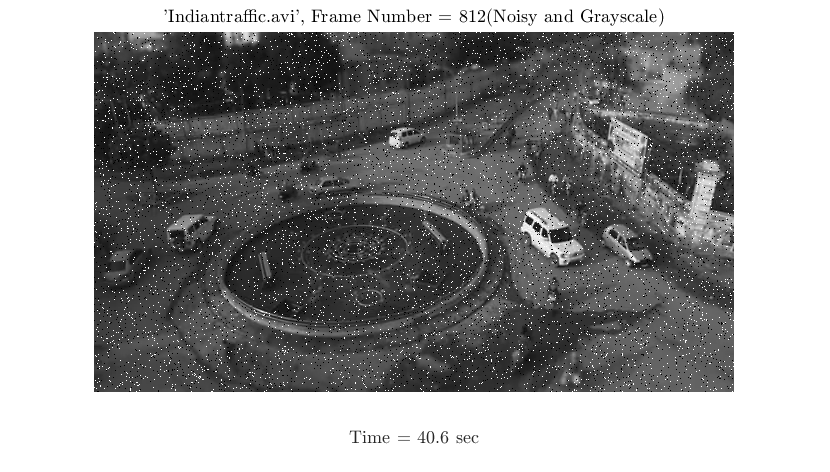

X = noisy_gray_film(:,:,frame_ind);
figure
imshow(X);
title("'Indiantraffic.avi', Frame Number = " + num2str(frame_ind) + "(Noisy and Grayscale)", Interpreter = "latex");
xlabel("Time = " + num2str(frame_ind/rgb_film_size(4)*duration_in_sec) + " sec", Interpreter = "latex");

lambda = 1 / sqrt(max(size(gray_film)));
maxIter = 500;
tol = 1e-5;
[L, S] = robust_pca(X, lambda/3, 10*lambda/3, tol, maxIter);

iter: 0001	err: 1.877084e-01
iter: 0010	err: 1.002227e-02
iter: 0020	err: 3.116823e-03
iter: 0030	err: 1.686191e-03
iter: 0040	err: 1.057318e-03
iter: 0050	err: 7.452500e-04
iter: 0060	err: 5.681574e-04
iter: 0070	err: 4.435781e-04
iter: 0080	err: 3.621255e-04
iter: 0090	err: 3.026596e-04
iter: 0100	err: 2.563775e-04
iter: 0110	err: 2.223690e-04
iter: 0120	err: 1.937940e-04
iter: 0130	err: 1.716247e-04
iter: 0140	err: 1.523119e-04
iter: 0150	err: 1.372946e-04
iter: 0160	err: 1.241489e-04
iter: 0170	err: 1.123903e-04
iter: 0180	err: 1.028545e-04
iter: 0190	err: 9.455926e-05
iter: 0200	err: 8.732438e-05
iter: 0210	err: 8.085616e-05
iter: 0220	err: 7.558423e-05
iter: 0230	err: 7.001584e-05
iter: 0240	err: 6.558425e-05
iter: 0250	err: 6.097661e-05
iter: 0260	err: 5.726987e-05
iter: 0270	err: 5.400367e-05
iter: 0280	err: 5.123554e-05
iter: 0290	err: 4.880802e-05
iter: 0300	err: 4.643683e-05
iter: 0310	err: 4.412589e-05
iter: 0320	err: 4.200852e-05
iter: 0330	err: 4.006767e-05
iter: 0340	err

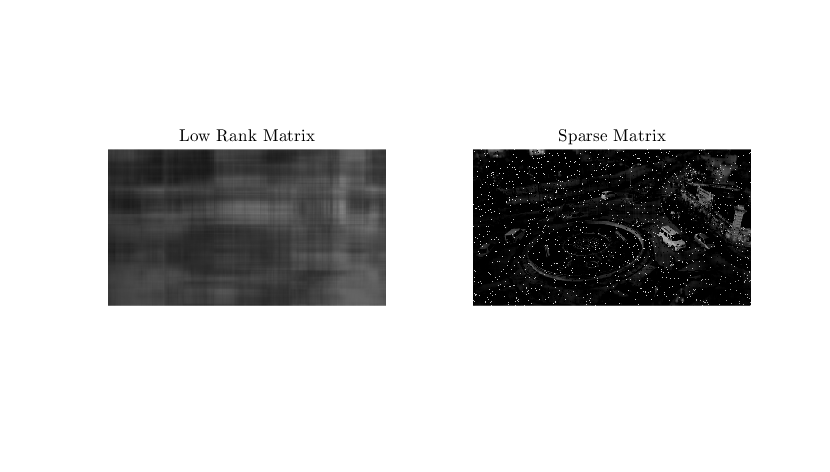

subplot(1,2,1)
imshow(L)
title("Low Rank Matrix", Interpreter = "latex");
subplot(1,2,2)
imshow(S)
title("Sparse Matrix", Interpreter = "latex");

`Flattening frames of video and vectorize the tensor.`

`**The seperation operation was only performed on 200 farmes.`

X = zeros(200, height*width);
for i = (1:200)
    frame = read(indiantraffic, i);
    frame = rgb2gray(frame);
    X(i,:) = reshape(frame,[],1);
end

`Apply robust pca to vectorized video.`

lambda = 0.00005;
tol = 1e-5;
maxIter = 5;
[lowRankTensor, sparseTensor] = robust_pca(X, lambda/3, 10*lambda/3, tol, maxIter);

iter: 0001	err: 1.226409e-03


`In the end, save a new video named "``foreground.avi"`` with the background removed and save the background in another video named ``"background.avi"``.`

foreground = VideoWriter('foreground.avi');
background = VideoWriter('background.avi');
foreground.FrameRate = frame_rate;
background.FrameRate = frame_rate;
open(foreground);
open(background);
range = 255;
map = repmat((0:range)'./range, 1, 3);
sparseTensor = medfilt2(sparseTensor, [5,1]);
for i = (1:size(X, 1))
    frame1 = reshape(X(i,:),height,[]);
    frame2 = reshape(lowRankTensor(i,:),height,[]);
    frame3 = reshape(abs(sparseTensor(i,:)),height,[]);
    frame2 = mat2gray(frame2);
    frame3 = mat2gray(frame3);
    frame2 = gray2ind(frame2,range);
    frame3 = gray2ind(frame3,range);
    frame2 = im2frame(frame2,map);
    frame3 = im2frame(frame3,map);
    writeVideo(foreground,frame3);
    writeVideo(background,frame2);
end
close(foreground);
close(background);